**Boundry analysis**

a script to iterate though the single exposure data and caluclate:

G - temp gradient across liquid-solid interface

R - interface velocity

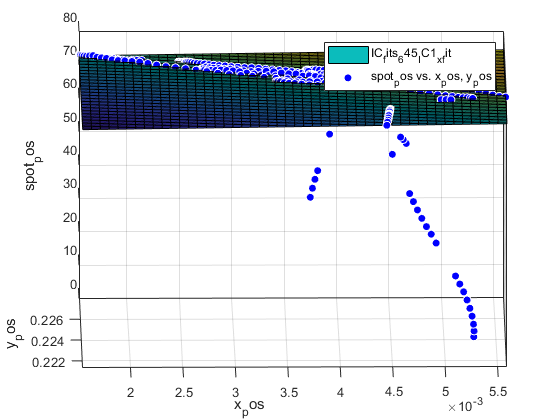

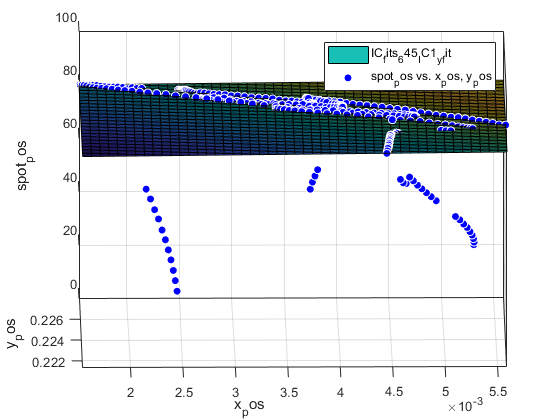

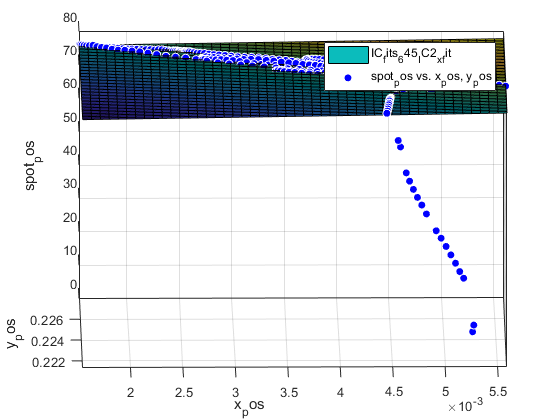

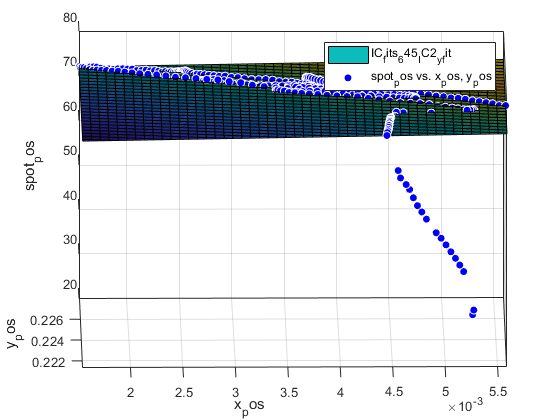

folder_name = '100W_6400us_50000fps';

folder_path = 'A:\Imperial College London\Hooper, Paul A - spots_v3';

load('intensity_ratio.mat')

fits=generate_image_alignment_surfaces(folder_path,folder_name);

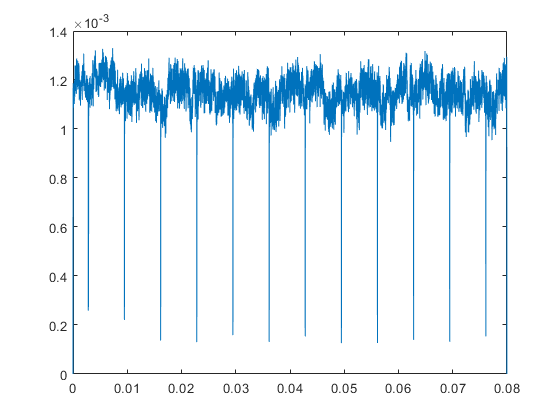


[processed_images, t_frame, spotradius, meanmidspottemp, boundarytempgradient,IC1_full,IC2_full]=process_laser_data(folder_path,folder_name,intensity_ratio,fits);

figure;
graph = plot(t_frame,spotradius);



% central pixel temperature and cooling rate
l=length(t_frame)

l = 4000

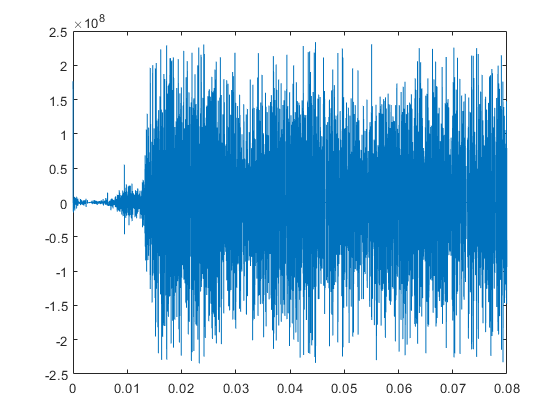

centre_temp = reshape(processed_images(64,64,1:l),[1,l]);
nonnanindex = find(~isnan(centre_temp));
cooling_rate = diff(centre_temp(nonnanindex))./diff(t_frame(nonnanindex));
cooling_times = zeros([1,length(cooling_rate)-1]);
for i=1:length(nonnanindex)-1
    cooling_times(i)=mean(t_frame(i:i+1));
end
figure;
plot(cooling_times,cooling_rate);

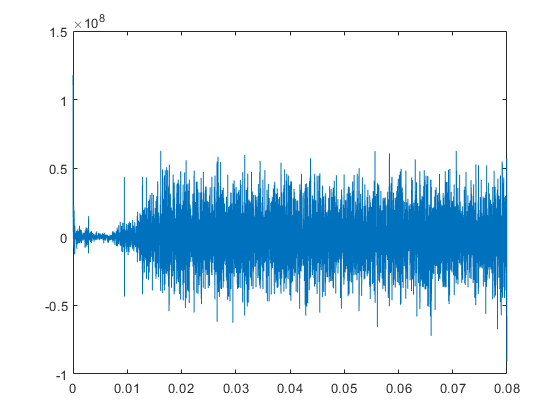



% mean temperautres of centre 8 squares
mean_centre_temp=nanmean(processed_images(60:68,60:68,1:l),[1,2]);
mean_centre_temp= reshape(mean_centre_temp,[1,l]);
nonnanindex = find(~isnan(mean_centre_temp));

mean_cooling_rate = diff(mean_centre_temp(nonnanindex))./diff(t_frame(nonnanindex));
mean_cooling_times = zeros([1,length(mean_cooling_rate)-1]);
for i=1:length(nonnanindex)-1
    mean_cooling_times(i)=mean(t_frame(i:i+1));
end
figure;
plot(mean_cooling_times,mean_cooling_rate);



% cooling rate at interface
images_as_lines = reshape(processed_images,[128*128,l+1]);
interface_pixel_index = zeros([500,l+1]);
MELT_THRESHOLD = 1370;%kelvin
uncertainty = 250;
half_division_width=1;
boundary_cooling_rate = zeros([1,l+1-2*half_division_width]);
boundary_cooling_rate_time = zeros([1,l+1-2*half_division_width]);
for i=1+half_division_width:l-half_division_width
    interface_pixel_index_temp = [];
    interface_pixel_index_temp = [find(MELT_THRESHOLD-uncertainty < images_as_lines(:,i) & images_as_lines(:,i) < MELT_THRESHOLD+uncertainty)];
    if ~isempty(interface_pixel_index_temp)
        interface_pixel_index(1:length(interface_pixel_index_temp),i)=interface_pixel_index_temp;
        temps_before = images_as_lines(interface_pixel_index_temp,i-half_division_width);
        temps_after = images_as_lines(interface_pixel_index_temp,i+half_division_width);
        temp_diffs = temps_after-temps_before;
        mean_temp_diff = nanmean(temp_diffs);
        if ~isnan(mean_temp_diff)
            boundary_cooling_rate(i) = mean_temp_diff/(t_frame(i+half_division_width)-t_frame(i-half_division_width));
            boundary_cooling_rate_time(i) = t_frame(i);
        end
    end
end
boundary_cooling_rate(boundary_cooling_rate==0) = nan;
pixels_by_temperature = zeros([128*128,l+1])

pixels_by_temperature =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0 


for i = 1:(l+1)
    line = images_as_lines(:,i);
    temp = sort(line(~isnan(line)),'descend');
    %temp(temp==0 | temp==293)=nan;
    pixels_by_temperature(1:length(temp),i) = temp;
    max(pixels_by_temperature(:,i))
end

ans = 0

ans = 4.9981e+03

ans = 4.9990e+03

ans = 4.9938e+03

ans = 5.0000e+03

ans = 4.9983e+03

ans = 4.9993e+03

ans = 4.9998e+03

ans = 4.9989e+03

ans = 4.9987e+03

ans = 4.9994e+03

ans = 4.9943e+03

ans = 4.9991e+03

ans = 4.9993e+03

ans = 4.9984e+03

ans = 4.9992e+03

ans = 4.9985e+03

ans = 4.9973e+03

ans = 4.9968e+03

ans = 4.9993e+03

ans = 4.9994e+03

ans = 4.9975e+03

ans = 4.9962e+03

ans = 4.9993e+03

ans = 4.9983e+03

ans = 4.9990e+03

ans = 4.9982e+03

ans = 4.9981e+03

ans = 4.9984e+03

ans = 4.9978e+03

ans = 4.9996e+03

ans = 4.9997e+03

ans = 4.9994e+03

ans = 4.9992e+03

ans = 4.9990e+03

ans = 4.9992e+03

ans = 4.9995e+03

ans = 4.9974e+03

ans = 4.9973e+03

ans = 4.9993e+03

ans = 4.9982e+03

ans = 4.9999e+03

ans = 4.9994e+03

ans = 4.9943e+03

ans = 4.9990e+03

ans = 4.9993e+03

ans = 4.9941e+03

ans = 4.9961e+03

ans = 4.9989e+03

ans = 4.9988e+03

ans = 4.9999e+03

ans = 4.9991e+03

ans = 4.9960e+03

ans = 4.9989e+03

ans = 4.9998e+03

ans = 4.9991e+03

ans = 4.9995e+03

ans = 4.9989e+03

ans = 4.9983e+03

ans = 4.9998e+03

ans = 4.9997e+03

ans = 4.9977e+03

ans = 4.9968e+03

ans = 4.9992e+03

ans = 4.9964e+03

ans = 4.9985e+03

ans = 4.9960e+03

ans = 4.9999e+03

ans = 4.9984e+03

ans = 4.9994e+03

ans = 4.9994e+03

ans = 4.9988e+03

ans = 4.9996e+03

ans = 4.9973e+03

ans = 4.9993e+03

ans = 4.9992e+03

ans = 4.9991e+03

ans = 4.9993e+03

ans = 4.9993e+03

ans = 5.0000e+03

ans = 4.9982e+03

ans = 4.9994e+03

ans = 4.9988e+03

ans = 4.9990e+03

ans = 4.9987e+03

ans = 4.9972e+03

ans = 4.9989e+03

ans = 4.9998e+03

ans = 4.9992e+03

ans = 4.9987e+03

ans = 4.9993e+03

ans = 4.9985e+03

ans = 4.9988e+03

ans = 4.9953e+03

ans = 4.9996e+03

ans = 4.9992e+03

ans = 4.9989e+03

ans = 4.9983e+03

ans = 4.9983e+03

ans = 4.9994e+03

ans = 4.9988e+03

ans = 4.9986e+03

ans = 4.9977e+03

ans = 4.9999e+03

ans = 4.9995e+03

ans = 4.9999e+03

ans = 4.9998e+03

ans = 4.9980e+03

ans = 4.9988e+03

ans = 4.9985e+03

ans = 4.9951e+03

ans = 4.9997e+03

ans = 4.9999e+03

ans = 4.9947e+03

ans = 4.9968e+03

ans = 4.9997e+03

ans = 4.9992e+03

ans = 4.9935e+03

ans = 4.9985e+03

ans = 4.9989e+03

ans = 4.9976e+03

ans = 4.9995e+03

ans = 5.0000e+03

ans = 4.9998e+03

ans = 4.9993e+03

ans = 4.9983e+03

ans = 4.9950e+03

ans = 4.9989e+03

ans = 4.9999e+03

ans = 4.9933e+03

ans = 4.9993e+03

ans = 4.9968e+03

ans = 4.9953e+03

ans = 4.9995e+03

ans = 4.9982e+03

ans = 4.9976e+03

ans = 4.9969e+03

ans = 4.9973e+03

ans = 4.9986e+03

ans = 4.9969e+03

ans = 4.9965e+03

ans = 4.9951e+03

ans = 4.8759e+03

ans = 4.9928e+03

ans = 4.9990e+03

ans = 4.9988e+03

ans = 4.9946e+03

ans = 4.9990e+03

ans = 4.9986e+03

ans = 4.9996e+03

ans = 4.9999e+03

ans = 4.9973e+03

ans = 4.9960e+03

ans = 4.9939e+03

ans = 4.9972e+03

ans = 4.9990e+03

ans = 4.9996e+03

ans = 4.9981e+03

ans = 4.9999e+03

ans = 4.9996e+03

ans = 4.9996e+03

ans = 4.9963e+03

ans = 4.9985e+03

ans = 4.9997e+03

ans = 4.9989e+03

ans = 4.9983e+03

ans = 4.9967e+03

ans = 4.9975e+03

ans = 4.9985e+03

ans = 4.9990e+03

ans = 4.9983e+03

ans = 4.9999e+03

ans = 4.9996e+03

ans = 4.9968e+03

ans = 4.9996e+03

ans = 4.9981e+03

ans = 4.9991e+03

ans = 4.9987e+03

ans = 4.9997e+03

ans = 4.9998e+03

ans = 4.9986e+03

ans = 4.9996e+03

ans = 4.9996e+03

ans = 4.9948e+03

ans = 4.9976e+03

ans = 4.9984e+03

ans = 4.9975e+03

ans = 4.9998e+03

ans = 4.9988e+03

ans = 4.9999e+03

ans = 4.9994e+03

ans = 4.9953e+03

ans = 4.9924e+03

ans = 4.9958e+03

ans = 4.9999e+03

ans = 4.9977e+03

ans = 4.9986e+03

ans = 4.9978e+03

ans = 4.9980e+03

ans = 4.9977e+03

ans = 4.9978e+03

ans = 4.9982e+03

ans = 4.9965e+03

ans = 4.9996e+03

ans = 4.9986e+03

ans = 4.9978e+03

ans = 4.9995e+03

ans = 4.9960e+03

ans = 4.9996e+03

ans = 4.9981e+03

ans = 4.9959e+03

ans = 4.9990e+03

ans = 4.9983e+03

ans = 4.9977e+03

ans = 4.9998e+03

ans = 4.9991e+03

ans = 4.9995e+03

ans = 4.9949e+03

ans = 4.9991e+03

ans = 4.9935e+03

ans = 4.9997e+03

ans = 4.9985e+03

ans = 4.9997e+03

ans = 4.9994e+03

ans = 4.9981e+03

ans = 4.9971e+03

ans = 4.9988e+03

ans = 4.9954e+03

ans = 4.9975e+03

ans = 4.9969e+03

ans = 4.9980e+03

ans = 5.0000e+03

ans = 4.9989e+03

ans = 4.9998e+03

ans = 4.9999e+03

ans = 4.9954e+03

ans = 4.9999e+03

ans = 4.9996e+03

ans = 4.9990e+03

ans = 4.9993e+03

ans = 4.9995e+03

ans = 4.9979e+03

ans = 4.9993e+03

ans = 4.9997e+03

ans = 4.9999e+03

ans = 4.9952e+03

ans = 4.9999e+03

ans = 4.9995e+03

ans = 4.9988e+03

ans = 4.9998e+03

ans = 4.9997e+03

ans = 4.9993e+03

ans = 4.9995e+03

ans = 4.9918e+03

ans = 4.9995e+03

ans = 4.9996e+03

ans = 4.9987e+03

ans = 4.9944e+03

ans = 4.9984e+03

ans = 4.9946e+03

ans = 4.9984e+03

ans = 4.9999e+03

ans = 4.9974e+03

ans = 5.0000e+03

ans = 4.9999e+03

ans = 4.9937e+03

ans = 4.9975e+03

ans = 4.9985e+03

ans = 4.9986e+03

ans = 4.9946e+03

ans = 4.9978e+03

ans = 4.9997e+03

ans = 4.9996e+03

ans = 4.9947e+03

ans = 4.9977e+03

ans = 4.9997e+03

ans = 4.9977e+03

ans = 4.9986e+03

ans = 4.9999e+03

ans = 4.9989e+03

ans = 4.9997e+03

ans = 4.9984e+03

ans = 4.9997e+03

ans = 4.9986e+03

ans = 4.9996e+03

ans = 5.0000e+03

ans = 4.9956e+03

ans = 4.9985e+03

ans = 4.9958e+03

ans = 4.9995e+03

ans = 4.9977e+03

ans = 4.9998e+03

ans = 5.0000e+03

ans = 4.9978e+03

ans = 4.9996e+03

ans = 4.9972e+03

ans = 4.9988e+03

ans = 4.9992e+03

ans = 4.9990e+03

ans = 4.9960e+03

ans = 4.9991e+03

ans = 4.9989e+03

ans = 4.9983e+03

ans = 4.9996e+03

ans = 4.9994e+03

ans = 4.9985e+03

ans = 4.9997e+03

ans = 4.9960e+03

ans = 4.9978e+03

ans = 4.9999e+03

ans = 4.9983e+03

ans = 4.9995e+03

ans = 4.9995e+03

ans = 4.9988e+03

ans = 4.9999e+03

ans = 4.9993e+03

ans = 4.9954e+03

ans = 4.9997e+03

ans = 4.9981e+03

ans = 4.9998e+03

ans = 4.9943e+03

ans = 4.9969e+03

ans = 4.9997e+03

ans = 4.9950e+03

ans = 4.9997e+03

ans = 4.9991e+03

ans = 4.9986e+03

ans = 4.9992e+03

ans = 4.9995e+03

ans = 4.9990e+03

ans = 4.9985e+03

ans = 4.9993e+03

ans = 4.9928e+03

ans = 4.9988e+03

ans = 4.9988e+03

ans = 4.9999e+03

ans = 4.9968e+03

ans = 4.9952e+03

ans = 4.9910e+03

ans = 4.9998e+03

ans = 4.9929e+03

ans = 4.9986e+03

ans = 4.9960e+03

ans = 4.9992e+03

ans = 5.0000e+03

ans = 4.9989e+03

ans = 4.9949e+03

ans = 4.9993e+03

ans = 4.9941e+03

ans = 5.0000e+03

ans = 4.9989e+03

ans = 4.9997e+03

ans = 4.9999e+03

ans = 4.9990e+03

ans = 4.9996e+03

ans = 4.9994e+03

ans = 4.9973e+03

ans = 4.9976e+03

ans = 4.9999e+03

ans = 4.9998e+03

ans = 4.9997e+03

ans = 4.9983e+03

ans = 4.9979e+03

ans = 4.9989e+03

ans = 4.9999e+03

ans = 4.9986e+03

ans = 4.9986e+03

ans = 4.9982e+03

ans = 4.9970e+03

ans = 4.9993e+03

ans = 4.9994e+03

ans = 4.9995e+03

ans = 4.9994e+03

ans = 4.9987e+03

ans = 4.9986e+03

ans = 4.9993e+03

ans = 4.9992e+03

ans = 4.9991e+03

ans = 4.9961e+03

ans = 4.9971e+03

ans = 4.9985e+03

ans = 4.9985e+03

ans = 4.9977e+03

ans = 5.0000e+03

ans = 4.9999e+03

ans = 4.9991e+03

ans = 4.9999e+03

ans = 4.9970e+03

ans = 4.9996e+03

ans = 4.9961e+03

ans = 4.9995e+03

ans = 4.9994e+03

ans = 4.9990e+03

ans = 4.9879e+03

ans = 4.9961e+03

ans = 4.9927e+03

ans = 4.9951e+03

ans = 4.9993e+03

ans = 4.9954e+03

ans = 4.9931e+03

ans = 4.9983e+03

ans = 4.9999e+03

ans = 4.9951e+03

ans = 4.9997e+03

ans = 4.9969e+03

ans = 4.9994e+03

ans = 4.9971e+03

ans = 4.9993e+03

ans = 4.9996e+03

ans = 4.9990e+03

ans = 4.9990e+03

ans = 4.9982e+03

ans = 4.9934e+03

ans = 4.9917e+03

ans = 4.9988e+03

ans = 4.9889e+03

ans = 4.9965e+03

ans = 4.9993e+03

ans = 4.9923e+03

ans = 4.9992e+03

ans = 4.9945e+03

ans = 4.9975e+03

ans = 4.9993e+03

ans = 4.9957e+03

ans = 4.9984e+03

ans = 4.9976e+03

ans = 4.9989e+03

ans = 4.9959e+03

ans = 4.9975e+03

ans = 4.9872e+03

ans = 4.9931e+03

ans = 4.9993e+03

ans = 4.9960e+03

ans = 4.9992e+03

ans = 4.9963e+03

ans = 4.9999e+03

ans = 4.9978e+03

ans = 4.9993e+03

ans = 4.9989e+03

ans = 4.9930e+03

ans = 4.9999e+03

ans = 4.9977e+03

ans = 4.9990e+03

ans = 4.9982e+03

ans = 4.9985e+03

ans = 4.9932e+03

ans = 4.9987e+03

ans = 4.9976e+03

ans = 4.9948e+03

ans = 4.9847e+03

ans = 4.9996e+03

ans = 4.9957e+03

ans = 4.9992e+03

ans = 4.9976e+03

ans = 4.9998e+03

ans = 4.9991e+03

ans = 5.0000e+03

ans = 4.9958e+03

ans = 4.9927e+03

ans = 4.9984e+03

ans = 4.9980e+03

ans = 4.9978e+03

ans = 4.9996e+03

ans = 4.9991e+03

ans = 5.0000e+03

ans = 4.9990e+03

ans = 4.9990e+03

ans = 4.9986e+03

ans = 4.9987e+03

ans = 4.9912e+03

ans = 4.9958e+03

ans = 4.9963e+03

ans = 4.9961e+03

ans = 4.9994e+03

ans = 4.8895e+03

ans = 4.9989e+03

ans = 4.9992e+03

ans = 4.9939e+03

ans = 4.9969e+03

ans = 4.9995e+03

ans = 4.9991e+03

ans = 4.9989e+03

ans = 4.9998e+03

ans = 4.9982e+03

ans = 4.9993e+03

ans = 4.9989e+03

ans = 4.9905e+03

ans = 4.9995e+03

ans = 4.9962e+03

ans = 4.9995e+03

ans = 4.9997e+03

ans = 4.9975e+03

ans = 4.9995e+03

ans = 4.9978e+03

ans = 4.9977e+03

ans = 5.0000e+03

ans = 4.9779e+03

ans = 4.9998e+03

ans = 4.9983e+03

ans = 4.9992e+03

ans = 4.9986e+03

ans = 4.9988e+03

ans = 4.9992e+03

ans = 4.9981e+03

ans = 4.9987e+03

ans = 4.9973e+03

ans = 4.9988e+03

ans = 4.9961e+03

ans = 4.9987e+03

ans = 4.9995e+03

ans = 4.9957e+03

ans = 4.9998e+03

ans = 4.9773e+03

ans = 4.9960e+03

ans = 4.9954e+03

ans = 4.9985e+03

ans = 4.9989e+03

ans = 4.9982e+03

ans = 4.9966e+03

ans = 4.9889e+03

ans = 4.9917e+03

ans = 4.9994e+03

ans = 4.9908e+03

ans = 4.9992e+03

ans = 4.9980e+03

ans = 4.9998e+03

ans = 4.9992e+03

ans = 4.9974e+03

ans = 4.9982e+03

ans = 4.9980e+03

ans = 4.9971e+03

ans = 4.9999e+03

ans = 4.9958e+03

ans = 4.9984e+03

ans = 4.9957e+03

ans = 4.9997e+03

ans = 4.9998e+03

ans = 4.9952e+03

ans = 4.9979e+03

ans = 4.9988e+03

ans = 4.9981e+03

ans = 4.9988e+03

ans = 4.9955e+03

ans = 4.9946e+03

ans = 4.9971e+03

ans = 4.9965e+03

ans = 4.9969e+03

ans = 4.9967e+03

ans = 4.9997e+03

ans = 4.9989e+03

ans = 4.9928e+03

ans = 4.9999e+03

ans = 4.9976e+03

ans = 4.9975e+03

ans = 4.9920e+03

ans = 5.0000e+03

ans = 4.9985e+03

ans = 4.9991e+03

ans = 4.9988e+03

ans = 4.9975e+03

ans = 4.9995e+03

ans = 4.9994e+03

ans = 4.9966e+03

ans = 4.9986e+03

ans = 4.9980e+03

ans = 4.9983e+03

ans = 4.9992e+03

ans = 4.9998e+03

ans = 4.9999e+03

ans = 4.9958e+03

ans = 4.9993e+03

ans = 4.9980e+03

ans = 4.9997e+03

ans = 4.9883e+03

ans = 4.9987e+03

ans = 4.9982e+03

ans = 4.9939e+03

ans = 4.9999e+03

ans = 4.9966e+03

ans = 4.9988e+03

ans = 4.9990e+03

ans = 4.9990e+03

ans = 4.9961e+03

ans = 4.9888e+03

ans = 4.9992e+03

ans = 4.9807e+03

ans = 4.9984e+03

ans = 4.9957e+03

ans = 4.9979e+03

ans = 4.9992e+03

ans = 4.9966e+03

ans = 4.9984e+03

ans = 4.9990e+03

ans = 4.9967e+03

ans = 4.9976e+03

ans = 4.9957e+03

ans = 4.9987e+03

ans = 4.9981e+03

ans = 4.9965e+03

ans = 4.9998e+03

ans = 4.9995e+03

ans = 4.9981e+03

ans = 4.9930e+03

ans = 4.9970e+03

ans = 4.9968e+03

ans = 4.9986e+03

ans = 4.9991e+03

ans = 4.9947e+03

ans = 4.9978e+03

ans = 4.9998e+03

ans = 4.9979e+03

ans = 4.9952e+03

ans = 4.9998e+03

ans = 4.9994e+03

ans = 4.9982e+03

ans = 4.9982e+03

ans = 4.9952e+03

ans = 4.9997e+03

ans = 4.9968e+03

ans = 4.9999e+03

ans = 4.9985e+03

ans = 4.9924e+03

ans = 4.9981e+03

ans = 4.9942e+03

ans = 4.9993e+03

ans = 4.9996e+03

ans = 4.9992e+03

ans = 4.9970e+03

ans = 4.9991e+03

ans = 4.9964e+03

ans = 4.9976e+03

ans = 4.9975e+03

ans = 4.9994e+03

ans = 4.9966e+03

ans = 4.9982e+03

ans = 4.9993e+03

ans = 4.9996e+03

ans = 4.9920e+03

ans = 4.9951e+03

ans = 4.9936e+03

ans = 4.9974e+03

ans = 4.9996e+03

ans = 4.9987e+03

ans = 4.9975e+03

ans = 4.9981e+03

ans = 4.9928e+03

ans = 4.9966e+03

ans = 4.9989e+03

ans = 4.9976e+03

ans = 4.9955e+03

ans = 4.9983e+03

ans = 4.9950e+03

ans = 4.9990e+03

ans = 4.9986e+03

ans = 4.9989e+03

ans = 4.9990e+03

ans = 4.9995e+03

ans = 4.9985e+03

ans = 4.9855e+03

ans = 4.9981e+03

ans = 4.9990e+03

ans = 4.9988e+03

ans = 4.9993e+03

ans = 4.9987e+03

ans = 4.9986e+03

ans = 4.9991e+03

ans = 4.9997e+03

ans = 4.9990e+03

ans = 4.9991e+03

ans = 4.9982e+03

ans = 4.9952e+03

ans = 4.9996e+03

ans = 4.9972e+03

ans = 4.9966e+03

ans = 4.9982e+03

ans = 4.9942e+03

ans = 4.9997e+03

ans = 4.9883e+03

ans = 4.9990e+03

ans = 4.9998e+03

ans = 4.9945e+03

ans = 4.9994e+03

ans = 4.9993e+03

ans = 4.9998e+03

ans = 4.9982e+03

ans = 4.9981e+03

ans = 4.9864e+03

ans = 4.9986e+03

ans = 4.9995e+03

ans = 4.9951e+03

ans = 4.9997e+03

ans = 4.9989e+03

ans = 4.9960e+03

ans = 4.9985e+03

ans = 4.9988e+03

ans = 4.9995e+03

ans = 4.9970e+03

ans = 5.0000e+03

ans = 4.9988e+03

ans = 4.9995e+03

ans = 4.9985e+03

ans = 4.9997e+03

ans = 4.9996e+03

ans = 4.9996e+03

ans = 4.9994e+03

ans = 4.9924e+03

ans = 4.9975e+03

ans = 4.9967e+03

ans = 4.9998e+03

ans = 4.9978e+03

ans = 4.9999e+03

ans = 4.9994e+03

ans = 4.9990e+03

ans = 4.9994e+03

ans = 4.9998e+03

ans = 4.9992e+03

ans = 4.9979e+03

ans = 4.9997e+03

ans = 4.9947e+03

ans = 4.9997e+03

ans = 4.9994e+03

ans = 4.9973e+03

ans = 4.9962e+03

ans = 4.9989e+03

ans = 4.9946e+03

ans = 4.9966e+03

ans = 4.9980e+03

ans = 4.9975e+03

ans = 4.9938e+03

ans = 4.9994e+03

ans = 4.9989e+03

ans = 4.9996e+03

ans = 4.9995e+03

ans = 4.9999e+03

ans = 4.9985e+03

ans = 4.9991e+03

ans = 5.0000e+03

ans = 4.9989e+03

ans = 4.9946e+03

ans = 4.9982e+03

ans = 4.9992e+03

ans = 4.9937e+03

ans = 4.9975e+03

ans = 4.9969e+03

ans = 4.9996e+03

ans = 4.9986e+03

ans = 4.9998e+03

ans = 4.9971e+03

ans = 4.9934e+03

ans = 4.9977e+03

ans = 5.0000e+03

ans = 4.9995e+03

ans = 4.9995e+03

ans = 4.9981e+03

ans = 4.9990e+03

ans = 4.9988e+03

ans = 4.9964e+03

ans = 4.9937e+03

ans = 4.9961e+03

ans = 4.9999e+03

ans = 4.9994e+03

ans = 4.9990e+03

ans = 4.9980e+03

ans = 4.9994e+03

ans = 4.9998e+03

ans = 4.9987e+03

ans = 4.9973e+03

ans = 4.9964e+03

ans = 4.9982e+03

ans = 4.9918e+03

ans = 4.9945e+03

ans = 4.9997e+03

ans = 4.9995e+03

ans = 4.9959e+03

ans = 4.9967e+03

ans = 4.9950e+03

ans = 4.9995e+03

ans = 4.9959e+03

ans = 4.9983e+03

ans = 4.9986e+03

ans = 4.9952e+03

ans = 4.9944e+03

ans = 4.9945e+03

ans = 4.9997e+03

ans = 4.9998e+03

ans = 4.9983e+03

ans = 4.9977e+03

ans = 4.9984e+03

ans = 4.9971e+03

ans = 4.9971e+03

ans = 4.9976e+03

ans = 4.9998e+03

ans = 4.9975e+03

ans = 4.9996e+03

ans = 4.9977e+03

ans = 4.9966e+03

ans = 4.9982e+03

ans = 4.9886e+03

ans = 4.9987e+03

ans = 4.9987e+03

ans = 4.9989e+03

ans = 4.9999e+03

ans = 4.9984e+03

ans = 4.9970e+03

ans = 4.9991e+03

ans = 4.9905e+03

ans = 4.9989e+03

ans = 4.9984e+03

ans = 4.9944e+03

ans = 4.9979e+03

ans = 4.9950e+03

ans = 4.9972e+03

ans = 4.9931e+03

ans = 4.9915e+03

ans = 4.9969e+03

ans = 4.9983e+03

ans = 4.9998e+03

ans = 4.9988e+03

ans = 4.9998e+03

ans = 4.9942e+03

ans = 4.9994e+03

ans = 4.9984e+03

ans = 4.9985e+03

ans = 4.9954e+03

ans = 4.9958e+03

ans = 4.9973e+03

ans = 4.9910e+03

ans = 4.9978e+03

ans = 4.9973e+03

ans = 4.9811e+03

ans = 4.9996e+03

ans = 4.9996e+03

ans = 4.9988e+03

ans = 4.9994e+03

ans = 4.9924e+03

ans = 4.9988e+03

ans = 4.9972e+03

ans = 4.9965e+03

ans = 4.9962e+03

ans = 4.9955e+03

ans = 4.9992e+03

ans = 4.9996e+03

ans = 4.9969e+03

ans = 4.9964e+03

ans = 4.9994e+03

ans = 4.9994e+03

ans = 4.9998e+03

ans = 4.9971e+03

ans = 4.9984e+03

ans = 4.9895e+03

ans = 4.9999e+03

ans = 4.9987e+03

ans = 4.9981e+03

ans = 4.9929e+03

ans = 4.9952e+03

ans = 4.9932e+03

ans = 4.9953e+03

ans = 4.9992e+03

ans = 4.9922e+03

ans = 4.9956e+03

ans = 4.9994e+03

ans = 4.9991e+03

ans = 4.9991e+03

ans = 5.0000e+03

ans = 4.9998e+03

ans = 4.9956e+03

ans = 4.9998e+03

ans = 4.9989e+03

ans = 4.9960e+03

ans = 4.9975e+03

ans = 4.9999e+03

ans = 4.9997e+03

ans = 4.9989e+03

ans = 4.9985e+03

ans = 4.9991e+03

ans = 4.9986e+03

ans = 4.9999e+03

ans = 5.0000e+03

ans = 4.9979e+03

ans = 4.9998e+03

ans = 4.9979e+03

ans = 4.9972e+03

ans = 4.9934e+03

ans = 4.9997e+03

ans = 4.9986e+03

ans = 4.9967e+03

ans = 4.9962e+03

ans = 4.9992e+03

ans = 4.9992e+03

ans = 4.9997e+03

ans = 4.9993e+03

ans = 4.9987e+03

ans = 4.9992e+03

ans = 4.9998e+03

ans = 4.9991e+03

ans = 4.9976e+03

ans = 4.9963e+03

ans = 4.9978e+03

ans = 5.0000e+03

ans = 4.9996e+03

ans = 4.9993e+03

ans = 4.9987e+03

ans = 4.9949e+03

ans = 4.9996e+03

ans = 4.9976e+03

ans = 4.9999e+03

ans = 4.9967e+03

ans = 4.9958e+03

ans = 4.9994e+03

ans = 4.9992e+03

ans = 4.9992e+03

ans = 4.9987e+03

ans = 4.9978e+03

ans = 4.9974e+03

ans = 4.9887e+03

ans = 4.9999e+03

ans = 4.9976e+03

ans = 4.9961e+03

ans = 4.9997e+03

ans = 4.9929e+03

ans = 4.9997e+03

ans = 4.9979e+03

ans = 4.9993e+03

ans = 4.9997e+03

ans = 4.9991e+03

ans = 4.9992e+03

ans = 4.9968e+03

ans = 4.9991e+03

ans = 4.9997e+03

ans = 4.9998e+03

ans = 4.9979e+03

ans = 4.9996e+03

ans = 4.9954e+03

ans = 4.9993e+03

ans = 4.9979e+03

ans = 4.9982e+03

ans = 4.9998e+03

ans = 4.9981e+03

ans = 4.9989e+03

ans = 4.9997e+03

ans = 4.9980e+03

ans = 4.9992e+03

ans = 4.9934e+03

ans = 4.9997e+03

ans = 4.9997e+03

ans = 4.9949e+03

ans = 4.9953e+03

ans = 4.9983e+03

ans = 4.9985e+03

ans = 4.9992e+03

ans = 4.9986e+03

ans = 4.9964e+03

ans = 4.9978e+03

ans = 4.9985e+03

ans = 4.9988e+03

ans = 4.9989e+03

ans = 4.9979e+03

ans = 4.9995e+03

ans = 4.9994e+03

ans = 4.9979e+03

ans = 4.9979e+03

ans = 4.9949e+03

ans = 4.9995e+03

ans = 4.9915e+03

ans = 4.9986e+03

ans = 4.9978e+03

ans = 4.9999e+03

ans = 4.9989e+03

ans = 4.9993e+03

ans = 4.9979e+03

ans = 4.9998e+03

ans = 4.9979e+03

ans = 4.9975e+03

ans = 4.9973e+03

ans = 4.9999e+03

ans = 5.0000e+03

ans = 4.9976e+03

ans = 4.9997e+03

ans = 4.9988e+03

ans = 4.9915e+03

ans = 4.9934e+03

ans = 4.9990e+03

ans = 4.9944e+03

ans = 4.9968e+03

ans = 4.9986e+03

ans = 4.9980e+03

ans = 4.9970e+03

ans = 4.9962e+03

ans = 4.9981e+03

ans = 4.9997e+03

ans = 4.9995e+03

ans = 4.9992e+03

ans = 4.9989e+03

ans = 4.9972e+03

ans = 4.9952e+03

ans = 4.9994e+03

ans = 4.9990e+03

ans = 4.9980e+03

ans = 4.9986e+03

ans = 4.9948e+03

ans = 4.9992e+03

ans = 4.9955e+03

ans = 4.9985e+03

ans = 4.9977e+03

ans = 4.9995e+03

ans = 4.9996e+03

ans = 4.9992e+03

ans = 4.9965e+03

ans = 4.9958e+03

ans = 4.9973e+03

ans = 4.9998e+03

ans = 4.9989e+03

ans = 4.9987e+03

ans = 4.9990e+03

ans = 4.9997e+03

ans = 4.9949e+03

ans = 5.0000e+03

ans = 4.9989e+03

ans = 4.9997e+03

ans = 4.9990e+03

ans = 5.0000e+03

ans = 4.9959e+03

ans = 4.9997e+03

ans = 4.9983e+03

ans = 4.9978e+03

ans = 4.9998e+03

ans = 4.9983e+03

ans = 4.9949e+03

ans = 4.9978e+03

ans = 4.9986e+03

ans = 4.9987e+03

ans = 4.9998e+03

ans = 4.9948e+03

ans = 4.9977e+03

ans = 4.9946e+03

ans = 4.9957e+03

ans = 4.9990e+03

ans = 4.9994e+03

ans = 4.9944e+03

ans = 4.9996e+03

ans = 4.9998e+03

ans = 4.9969e+03

ans = 5.0000e+03

ans = 4.9980e+03

ans = 4.9987e+03

ans = 4.9999e+03

ans = 4.9973e+03

ans = 4.9912e+03

ans = 4.9998e+03

ans = 4.9960e+03

ans = 4.9989e+03

ans = 4.9937e+03

ans = 4.9991e+03

ans = 4.9999e+03

ans = 4.9962e+03

ans = 4.9948e+03

ans = 4.9992e+03

ans = 4.9946e+03

ans = 4.9989e+03

ans = 4.9962e+03

ans = 4.9989e+03

ans = 4.9973e+03

ans = 4.9994e+03

ans = 4.9975e+03

ans = 5.0000e+03

ans = 4.9985e+03

ans = 4.9976e+03

ans = 4.9966e+03

ans = 4.9987e+03

ans = 4.9970e+03

ans = 4.9964e+03

ans = 4.9994e+03

ans = 4.9996e+03

ans = 4.9988e+03

ans = 4.9944e+03

ans = 4.9986e+03

ans = 4.9999e+03

ans = 4.9991e+03

ans = 4.9979e+03

ans = 4.9995e+03

ans = 4.9997e+03

ans = 4.9993e+03

ans = 4.9998e+03

ans = 4.9996e+03

ans = 4.9971e+03

ans = 4.9890e+03

ans = 4.9918e+03

ans = 4.9962e+03

ans = 4.9978e+03

ans = 4.9974e+03

ans = 4.9986e+03

ans = 4.9969e+03

ans = 4.9977e+03

ans = 4.9957e+03

ans = 4.9975e+03

ans = 4.9999e+03

ans = 4.9899e+03

ans = 4.9931e+03

ans = 4.9977e+03

ans = 4.9976e+03

ans = 4.9974e+03

ans = 4.9968e+03

ans = 4.9964e+03

ans = 4.9972e+03

ans = 4.9989e+03

ans = 4.9978e+03

ans = 4.9996e+03

ans = 4.9988e+03

ans = 4.9947e+03

ans = 4.9994e+03

ans = 4.9987e+03

ans = 4.9986e+03

ans = 4.9989e+03

ans = 4.9990e+03

ans = 4.9994e+03

ans = 4.9980e+03

ans = 4.9967e+03

ans = 4.9997e+03

ans = 4.9983e+03

ans = 4.9976e+03

ans = 4.9980e+03

ans = 4.9993e+03

ans = 4.9944e+03

ans = 4.9975e+03

ans = 4.9992e+03

ans = 4.9994e+03

ans = 4.9981e+03

ans = 4.9983e+03

ans = 4.9973e+03

ans = 5.0000e+03

ans = 4.9994e+03

ans = 4.9977e+03

ans = 4.9981e+03

ans = 4.9976e+03

ans = 4.9958e+03

ans = 4.9998e+03

ans = 4.9973e+03

ans = 4.9990e+03

ans = 4.9997e+03

ans = 4.9972e+03

ans = 4.9990e+03

ans = 4.9121e+03

ans = 4.9979e+03

ans = 4.9999e+03

ans = 4.9985e+03

ans = 4.9964e+03

ans = 4.9996e+03

ans = 4.9971e+03

ans = 4.9985e+03

ans = 4.9996e+03

ans = 4.9996e+03

ans = 4.9940e+03

ans = 4.9940e+03

ans = 4.9991e+03

ans = 4.9983e+03

ans = 4.9993e+03

ans = 4.9997e+03

ans = 4.9999e+03

ans = 5.0000e+03

ans = 4.9905e+03

ans = 4.9972e+03

ans = 4.9943e+03

ans = 4.9997e+03

ans = 4.9935e+03

ans = 4.9982e+03

ans = 4.9984e+03

ans = 4.9999e+03

ans = 4.9992e+03

ans = 4.9961e+03

ans = 4.9997e+03

ans = 4.9997e+03

ans = 4.9973e+03

ans = 4.9995e+03

ans = 4.9988e+03

ans = 4.9978e+03

ans = 4.9993e+03

ans = 4.9938e+03

ans = 4.9989e+03

ans = 4.9986e+03

ans = 4.9977e+03

ans = 4.9984e+03

ans = 4.9989e+03

ans = 4.9977e+03

ans = 4.9988e+03

ans = 4.9993e+03

ans = 4.9999e+03

ans = 4.9983e+03

ans = 4.9989e+03

ans = 4.9997e+03

ans = 4.9973e+03

ans = 4.9947e+03

ans = 4.9994e+03

ans = 4.9982e+03

ans = 4.9985e+03

ans = 4.9988e+03

ans = 4.9973e+03

ans = 4.9979e+03

ans = 4.9972e+03

ans = 4.9999e+03

ans = 4.9997e+03

ans = 4.9985e+03

ans = 4.9941e+03

ans = 4.9997e+03

ans = 4.9993e+03

ans = 4.9941e+03

ans = 4.9993e+03

ans = 4.9998e+03

ans = 4.9994e+03

ans = 4.9948e+03

ans = 4.9996e+03

ans = 4.9893e+03

ans = 4.9982e+03

ans = 4.9925e+03

ans = 4.9997e+03

ans = 4.9998e+03

ans = 4.9976e+03

ans = 4.9999e+03

ans = 4.9995e+03

ans = 4.9979e+03

ans = 4.9953e+03

ans = 4.9999e+03

ans = 4.9955e+03

ans = 4.9979e+03

ans = 4.9955e+03

ans = 4.9987e+03

ans = 4.9992e+03

ans = 4.9972e+03

ans = 4.9991e+03

ans = 4.9996e+03

ans = 4.9989e+03

ans = 4.9991e+03

ans = 4.9984e+03

ans = 4.9993e+03

ans = 4.9992e+03

ans = 4.9992e+03

ans = 4.9977e+03

ans = 4.9981e+03

ans = 4.9948e+03

ans = 4.9959e+03

ans = 4.9998e+03

ans = 4.9970e+03

ans = 5.0000e+03

ans = 5.0000e+03

ans = 4.9981e+03

ans = 4.9946e+03

ans = 4.9964e+03

ans = 4.9993e+03

ans = 4.9987e+03

ans = 4.9982e+03

ans = 4.9998e+03

ans = 4.9997e+03

ans = 4.9999e+03

ans = 4.9991e+03

ans = 4.9989e+03

ans = 4.9989e+03

ans = 5.0000e+03

ans = 4.9998e+03

ans = 4.9977e+03

ans = 4.9977e+03

ans = 4.9967e+03

ans = 4.9992e+03

ans = 5.0000e+03

ans = 4.9992e+03

ans = 4.9968e+03

ans = 4.9989e+03

ans = 5.0000e+03

ans = 4.9931e+03

ans = 4.9986e+03

ans = 4.9998e+03

ans = 4.9932e+03

ans = 4.9995e+03

ans = 4.9967e+03

ans = 4.9999e+03

ans = 4.9990e+03

ans = 4.9999e+03

ans = 5.0000e+03

ans = 4.9943e+03

ans = 4.9999e+03

ans = 4.9996e+03

ans = 4.9996e+03

ans = 4.9981e+03

ans = 4.9995e+03

ans = 4.9988e+03

ans = 4.9985e+03

ans = 4.9977e+03

ans = 4.9960e+03

ans = 4.9931e+03

ans = 4.9991e+03

ans = 4.9974e+03

ans = 4.9985e+03

ans = 4.9994e+03

ans = 4.9900e+03

ans = 4.9998e+03

ans = 4.9965e+03

ans = 4.9988e+03

ans = 4.9973e+03

ans = 4.9977e+03

ans = 4.9970e+03

ans = 4.9988e+03

ans = 5.0000e+03

ans = 4.9935e+03

ans = 4.9951e+03

ans = 4.9990e+03

ans = 4.9954e+03

ans = 4.9956e+03

ans = 4.9952e+03

ans = 4.9998e+03

ans = 4.9974e+03

ans = 4.9982e+03

ans = 4.9964e+03

ans = 4.9978e+03

ans = 4.9975e+03

ans = 4.9965e+03

ans = 4.9991e+03

ans = 4.9953e+03

ans = 4.9971e+03

ans = 5.0000e+03

ans = 4.9982e+03

ans = 4.9971e+03

ans = 4.9969e+03

ans = 4.9899e+03

ans = 4.9987e+03

ans = 4.9975e+03

ans = 4.9991e+03

ans = 4.9984e+03

ans = 4.9968e+03

ans = 4.9962e+03

ans = 4.9997e+03

ans = 4.9974e+03

ans = 4.9956e+03

ans = 4.9984e+03

ans = 4.9901e+03

ans = 4.9995e+03

ans = 4.9963e+03

ans = 4.9995e+03

ans = 4.9870e+03

ans = 4.9995e+03

ans = 4.9968e+03

ans = 4.9980e+03

ans = 4.9990e+03

ans = 4.9981e+03

ans = 4.9948e+03

ans = 4.9996e+03

ans = 4.9986e+03

ans = 4.9999e+03

ans = 4.9967e+03

ans = 4.9932e+03

ans = 4.9964e+03

ans = 4.9988e+03

ans = 4.9971e+03

ans = 4.9983e+03

ans = 4.9959e+03

ans = 4.9993e+03

ans = 4.9986e+03

ans = 4.9917e+03

ans = 4.9960e+03

ans = 4.9991e+03

ans = 4.9986e+03

ans = 4.9996e+03

ans = 4.9991e+03

ans = 4.9995e+03

ans = 4.9981e+03

ans = 4.9979e+03

ans = 4.9968e+03

ans = 4.9994e+03

ans = 4.9998e+03

ans = 4.9994e+03

ans = 5.0000e+03

ans = 4.9996e+03

ans = 4.9999e+03

ans = 4.9962e+03

ans = 4.9953e+03

ans = 4.9997e+03

ans = 4.9970e+03

ans = 4.9963e+03

ans = 4.9999e+03

ans = 4.9983e+03

ans = 4.9990e+03

ans = 5.0000e+03

ans = 4.9980e+03

ans = 4.9983e+03

ans = 4.9994e+03

ans = 4.9992e+03

ans = 4.9963e+03

ans = 4.9933e+03

ans = 4.9988e+03

ans = 4.9954e+03

ans = 4.9996e+03

ans = 4.9994e+03

ans = 4.9849e+03

ans = 4.9982e+03

ans = 4.9990e+03

ans = 4.9989e+03

ans = 4.9945e+03

ans = 4.9999e+03

ans = 4.9890e+03

ans = 4.9971e+03

ans = 4.9987e+03

ans = 4.9961e+03

ans = 4.9992e+03

ans = 4.9990e+03

ans = 4.9979e+03

ans = 4.9977e+03

ans = 4.9991e+03

ans = 4.9996e+03

ans = 4.9978e+03

ans = 4.9998e+03

ans = 4.9952e+03

ans = 4.9991e+03

ans = 4.9956e+03

ans = 4.9996e+03

ans = 4.9996e+03

ans = 4.9986e+03

ans = 4.9969e+03

ans = 4.9977e+03

ans = 4.9993e+03

ans = 4.9952e+03

ans = 4.9982e+03

ans = 4.9962e+03

ans = 4.9938e+03

ans = 4.9981e+03

ans = 5.0000e+03

ans = 4.9977e+03

ans = 4.9990e+03

ans = 4.9985e+03

ans = 4.9967e+03

ans = 4.9990e+03

ans = 4.9998e+03

ans = 4.9995e+03

ans = 4.9999e+03

ans = 4.9978e+03

ans = 4.9994e+03

ans = 4.9978e+03

ans = 4.9962e+03

ans = 4.9993e+03

ans = 4.9999e+03

ans = 4.9974e+03

ans = 4.9974e+03

ans = 4.9986e+03

ans = 4.9957e+03

ans = 4.9997e+03

ans = 4.9950e+03

ans = 4.9994e+03

ans = 4.9978e+03

ans = 4.9984e+03

ans = 4.9957e+03

ans = 4.9932e+03

ans = 4.9992e+03

ans = 4.9974e+03

ans = 4.9977e+03

ans = 4.9960e+03

ans = 4.9926e+03

ans = 4.9953e+03

ans = 4.9987e+03

ans = 4.9992e+03

ans = 4.9930e+03

ans = 4.9934e+03

ans = 4.9923e+03

ans = 4.9973e+03

ans = 4.9986e+03

ans = 4.9982e+03

ans = 4.9986e+03

ans = 4.9958e+03

ans = 4.9964e+03

ans = 4.9997e+03

ans = 4.9928e+03

ans = 4.9976e+03

ans = 4.9944e+03

ans = 4.9978e+03

ans = 4.9977e+03

ans = 4.9998e+03

ans = 4.9995e+03

ans = 4.9971e+03

ans = 4.9921e+03

ans = 4.9270e+03

ans = 4.9989e+03

ans = 4.9990e+03

ans = 4.9889e+03

ans = 4.9985e+03

ans = 4.9997e+03

ans = 4.9975e+03

ans = 4.9976e+03

ans = 4.9994e+03

ans = 4.9988e+03

ans = 4.9981e+03

ans = 4.9984e+03

ans = 4.9990e+03

ans = 4.9995e+03

ans = 4.9970e+03

ans = 4.9996e+03

ans = 4.9997e+03

ans = 4.9951e+03

ans = 4.9979e+03

ans = 4.9990e+03

ans = 4.9979e+03

ans = 4.9998e+03

ans = 4.9995e+03

ans = 4.9989e+03

ans = 4.9978e+03

ans = 4.9992e+03

ans = 4.9958e+03

ans = 4.9964e+03

ans = 4.9987e+03

ans = 4.9999e+03

ans = 4.9987e+03

ans = 4.9907e+03

ans = 4.9977e+03

ans = 4.9987e+03

ans = 4.9983e+03

ans = 4.9912e+03

ans = 5.0000e+03

ans = 4.9973e+03

ans = 4.9978e+03

ans = 4.9939e+03

ans = 4.9985e+03

ans = 4.9990e+03

ans = 4.9981e+03

ans = 4.9973e+03

ans = 4.9896e+03

ans = 4.9932e+03

ans = 4.9998e+03

ans = 4.9999e+03

ans = 4.9968e+03

ans = 4.9997e+03

ans = 4.9963e+03

ans = 4.9993e+03

ans = 4.9932e+03

ans = 4.9991e+03

ans = 4.9983e+03

ans = 4.9999e+03

ans = 4.9967e+03

ans = 4.9988e+03

ans = 4.9913e+03

ans = 4.9985e+03

ans = 4.9957e+03

ans = 4.9990e+03

ans = 4.9989e+03

ans = 4.9962e+03

ans = 4.9988e+03

ans = 4.9971e+03

ans = 4.9986e+03

ans = 4.9978e+03

ans = 4.9967e+03

ans = 4.9976e+03

ans = 4.9975e+03

ans = 4.9963e+03

ans = 4.9899e+03

ans = 4.9987e+03

ans = 4.9953e+03

ans = 4.9939e+03

ans = 4.9977e+03

ans = 4.9993e+03

ans = 4.9962e+03

ans = 4.9957e+03

ans = 4.9996e+03

ans = 4.9992e+03

ans = 4.9998e+03

ans = 4.9993e+03

ans = 4.9950e+03

ans = 4.9970e+03

ans = 4.9938e+03

ans = 4.9977e+03

ans = 4.9953e+03

ans = 4.9989e+03

ans = 4.9990e+03

ans = 4.9983e+03

ans = 4.9999e+03

ans = 4.9993e+03

ans = 4.9982e+03

ans = 4.9987e+03

ans = 4.9996e+03

ans = 4.9955e+03

ans = 4.9969e+03

ans = 4.9982e+03

ans = 4.9978e+03

ans = 4.9994e+03

ans = 4.9968e+03

ans = 4.9989e+03

ans = 4.9971e+03

ans = 4.9998e+03

ans = 4.9963e+03

ans = 4.9936e+03

ans = 4.9983e+03

ans = 4.9934e+03

ans = 4.9999e+03

ans = 4.9987e+03

ans = 4.9965e+03

ans = 4.9991e+03

ans = 4.9972e+03

ans = 4.9999e+03

ans = 4.9993e+03

ans = 4.9924e+03

ans = 4.9992e+03

ans = 4.9919e+03

ans = 4.9967e+03

ans = 4.9993e+03

ans = 4.9986e+03

ans = 4.9984e+03

ans = 4.9972e+03

ans = 4.9993e+03

ans = 4.9918e+03

ans = 4.9958e+03

ans = 4.9995e+03

ans = 4.9931e+03

ans = 4.9971e+03

ans = 4.9997e+03

ans = 4.9970e+03

ans = 4.9981e+03

ans = 4.9981e+03

ans = 4.9998e+03

ans = 4.9943e+03

ans = 4.9959e+03

ans = 4.9997e+03

ans = 4.9979e+03

ans = 4.9992e+03

ans = 4.9999e+03

ans = 4.9993e+03

ans = 4.9990e+03

ans = 4.9971e+03

ans = 4.9983e+03

ans = 4.9995e+03

ans = 4.9996e+03

ans = 4.9968e+03

ans = 4.9997e+03

ans = 4.9997e+03

ans = 4.9961e+03

ans = 4.9971e+03

ans = 4.9887e+03

ans = 4.9949e+03

ans = 4.9996e+03

ans = 4.9978e+03

ans = 4.9964e+03

ans = 4.9955e+03

ans = 4.9944e+03

ans = 4.9974e+03

ans = 4.9996e+03

ans = 4.9982e+03

ans = 4.9997e+03

ans = 4.9984e+03

ans = 4.9973e+03

ans = 4.9997e+03

ans = 4.9953e+03

ans = 4.9994e+03

ans = 4.9919e+03

ans = 4.9999e+03

ans = 4.9993e+03

ans = 4.9968e+03

ans = 4.9988e+03

ans = 4.9990e+03

ans = 4.9990e+03

ans = 4.9928e+03

ans = 4.9981e+03

ans = 5.0000e+03

ans = 5.0000e+03

ans = 4.9943e+03

ans = 4.9974e+03

ans = 4.9975e+03

ans = 4.9980e+03

ans = 4.9991e+03

ans = 4.9981e+03

ans = 4.9972e+03

ans = 4.9989e+03

ans = 4.9984e+03

ans = 4.9987e+03

ans = 4.9986e+03

ans = 4.9997e+03

ans = 4.9857e+03

ans = 4.9941e+03

ans = 4.9996e+03

ans = 4.9974e+03

ans = 4.9917e+03

ans = 4.9982e+03

ans = 4.9995e+03

ans = 4.9993e+03

ans = 4.9989e+03

ans = 4.9931e+03

ans = 4.9890e+03

ans = 4.9975e+03

ans = 4.9972e+03

ans = 4.9975e+03

ans = 4.9988e+03

ans = 4.9975e+03

ans = 4.9987e+03

ans = 4.9980e+03

ans = 4.9894e+03

ans = 4.9983e+03

ans = 4.9967e+03

ans = 4.9979e+03

ans = 4.9950e+03

ans = 4.9948e+03

ans = 4.9980e+03

ans = 4.9989e+03

ans = 4.9999e+03

ans = 4.9974e+03

ans = 4.9843e+03

ans = 4.9970e+03

ans = 4.9994e+03

ans = 4.9991e+03

ans = 4.9994e+03

ans = 4.9998e+03

ans = 4.9991e+03

ans = 4.9947e+03

ans = 4.9986e+03

ans = 4.9950e+03

ans = 4.9999e+03

ans = 4.9971e+03

ans = 4.9970e+03

ans = 4.9986e+03

ans = 4.9995e+03

ans = 4.9996e+03

ans = 4.9992e+03

ans = 4.9992e+03

ans = 4.9926e+03

ans = 4.9901e+03

ans = 4.9971e+03

ans = 4.9970e+03

ans = 4.9999e+03

ans = 5.0000e+03

ans = 4.9977e+03

ans = 4.9968e+03

ans = 4.9997e+03

ans = 4.9993e+03

ans = 4.9951e+03

ans = 4.9984e+03

ans = 4.9990e+03

ans = 4.9988e+03

ans = 4.9981e+03

ans = 4.9971e+03

ans = 4.9992e+03

ans = 4.9998e+03

ans = 4.9999e+03

ans = 4.9936e+03

ans = 4.9966e+03

ans = 4.9990e+03

ans = 4.9994e+03

ans = 4.9979e+03

ans = 4.9879e+03

ans = 4.9992e+03

ans = 4.9974e+03

ans = 4.9985e+03

ans = 4.9993e+03

ans = 4.9998e+03

ans = 4.9994e+03

ans = 4.9997e+03

ans = 4.9995e+03

ans = 4.9984e+03

ans = 4.9989e+03

ans = 4.9981e+03

ans = 4.9977e+03

ans = 4.9983e+03

ans = 4.9980e+03

ans = 4.9988e+03

ans = 4.9987e+03

ans = 4.9992e+03

ans = 4.9990e+03

ans = 4.9920e+03

ans = 5.0000e+03

ans = 4.9966e+03

ans = 4.9994e+03

ans = 4.9983e+03

ans = 4.9990e+03

ans = 4.9991e+03

ans = 4.9996e+03

ans = 4.9962e+03

ans = 4.9925e+03

ans = 4.9986e+03

ans = 4.9924e+03

ans = 4.9986e+03

ans = 4.9977e+03

ans = 4.9991e+03

ans = 4.9991e+03

ans = 4.9968e+03

ans = 4.9944e+03

ans = 4.9926e+03

ans = 4.9990e+03

ans = 4.9995e+03

ans = 4.9980e+03

ans = 4.9979e+03

ans = 4.9975e+03

ans = 4.9969e+03

ans = 4.9942e+03

ans = 4.9994e+03

ans = 4.9989e+03

ans = 4.9985e+03

ans = 4.9986e+03

ans = 4.9950e+03

ans = 4.9983e+03

ans = 4.9998e+03

ans = 4.9991e+03

ans = 4.9993e+03

ans = 4.9983e+03

ans = 4.9977e+03

ans = 4.9996e+03

ans = 4.9980e+03

ans = 4.9950e+03

ans = 4.9970e+03

ans = 4.9993e+03

ans = 4.9952e+03

ans = 4.9940e+03

ans = 4.9988e+03

ans = 4.9997e+03

ans = 4.9992e+03

ans = 4.9995e+03

ans = 4.9942e+03

ans = 4.9972e+03

ans = 4.9989e+03

ans = 4.9999e+03

ans = 4.9986e+03

ans = 4.4374e+03

ans = 4.9957e+03

ans = 4.9991e+03

ans = 4.9958e+03

ans = 4.9999e+03

ans = 4.9989e+03

ans = 4.9970e+03

ans = 4.9977e+03

ans = 4.9978e+03

ans = 4.9962e+03

ans = 4.9989e+03

ans = 4.9952e+03

ans = 4.9962e+03

ans = 5.0000e+03

ans = 4.9955e+03

ans = 4.9984e+03

ans = 4.9961e+03

ans = 4.9971e+03

ans = 4.9889e+03

ans = 4.9984e+03

ans = 4.9998e+03

ans = 4.9976e+03

ans = 4.9995e+03

ans = 4.9932e+03

ans = 4.9938e+03

ans = 4.9950e+03

ans = 4.9990e+03

ans = 4.9945e+03

ans = 4.9976e+03

ans = 4.9977e+03

ans = 4.9995e+03

ans = 4.9941e+03

ans = 4.9943e+03

ans = 4.9973e+03

ans = 4.9991e+03

ans = 4.9990e+03

ans = 4.9965e+03

ans = 4.9995e+03

ans = 4.9970e+03

ans = 4.9979e+03

ans = 4.9997e+03

ans = 4.9993e+03

ans = 4.9981e+03

ans = 4.9982e+03

ans = 4.9994e+03

ans = 4.9999e+03

ans = 4.9950e+03

ans = 4.9975e+03

ans = 4.9992e+03

ans = 4.9978e+03

ans = 4.9994e+03

ans = 4.9977e+03

ans = 4.9948e+03

ans = 4.9990e+03

ans = 4.9994e+03

ans = 4.9998e+03

ans = 4.9920e+03

ans = 4.9968e+03

ans = 4.9992e+03

ans = 4.9999e+03

ans = 4.9998e+03

ans = 4.9983e+03

ans = 4.9940e+03

ans = 4.9966e+03

ans = 4.9993e+03

ans = 4.9939e+03

ans = 4.9999e+03

ans = 4.9978e+03

ans = 4.9988e+03

ans = 4.9997e+03

ans = 4.9986e+03

ans = 4.9988e+03

ans = 4.9922e+03

ans = 4.9963e+03

ans = 4.9998e+03

ans = 4.9972e+03

ans = 4.9988e+03

ans = 4.9996e+03

ans = 5.0000e+03

ans = 4.9997e+03

ans = 4.9907e+03

ans = 4.9996e+03

ans = 4.9992e+03

ans = 4.9999e+03

ans = 4.9949e+03

ans = 4.9953e+03

ans = 4.9990e+03

ans = 4.9965e+03

ans = 4.9939e+03

ans = 4.9995e+03

ans = 4.9996e+03

ans = 4.9953e+03

ans = 4.9984e+03

ans = 4.9981e+03

ans = 5.0000e+03

ans = 4.9996e+03

ans = 4.9999e+03

ans = 4.9947e+03

ans = 4.9954e+03

ans = 4.9985e+03

ans = 4.9937e+03

ans = 4.9997e+03

ans = 4.9991e+03

ans = 4.9972e+03

ans = 4.9971e+03

ans = 4.9963e+03

ans = 4.9975e+03

ans = 4.9989e+03

ans = 4.9993e+03

ans = 4.9995e+03

ans = 4.9980e+03

ans = 4.9955e+03

ans = 4.9982e+03

ans = 4.9959e+03

ans = 4.9991e+03

ans = 4.9984e+03

ans = 4.9940e+03

ans = 4.9944e+03

ans = 4.9969e+03

ans = 4.9972e+03

ans = 4.9995e+03

ans = 4.9971e+03

ans = 4.9993e+03

ans = 4.9987e+03

ans = 4.9995e+03

ans = 4.9990e+03

ans = 4.9991e+03

ans = 4.9985e+03

ans = 4.9994e+03

ans = 4.9984e+03

ans = 4.9993e+03

ans = 4.9990e+03

ans = 4.9963e+03

ans = 4.9978e+03

ans = 4.9978e+03

ans = 4.9996e+03

ans = 4.9943e+03

ans = 4.9990e+03

ans = 4.9962e+03

ans = 4.9989e+03

ans = 4.9990e+03

ans = 4.9966e+03

ans = 4.9996e+03

ans = 4.9911e+03

ans = 4.9960e+03

ans = 4.9988e+03

ans = 4.9981e+03

ans = 4.9974e+03

ans = 4.9988e+03

ans = 4.9986e+03

ans = 5.0000e+03

ans = 4.9988e+03

ans = 4.9985e+03

ans = 4.9975e+03

ans = 4.9991e+03

ans = 4.9957e+03

ans = 4.9978e+03

ans = 4.9939e+03

ans = 4.9936e+03

ans = 4.9965e+03

ans = 4.9993e+03

ans = 4.9962e+03

ans = 4.9989e+03

ans = 4.9966e+03

ans = 4.9936e+03

ans = 4.9996e+03

ans = 4.9917e+03

ans = 4.9998e+03

ans = 5.0000e+03

ans = 4.9956e+03

ans = 4.9994e+03

ans = 4.9966e+03

ans = 4.9917e+03

ans = 4.9954e+03

ans = 4.9996e+03

ans = 4.9998e+03

ans = 4.9984e+03

ans = 4.9992e+03

ans = 4.9926e+03

ans = 4.9996e+03

ans = 4.9985e+03

ans = 4.9999e+03

ans = 4.9987e+03

%save(strcat('Spot_data_new\',folder_name),'spotradius','t_frame','mean_centre_temp');
%title(folder_name)
%xlim([0.004,0.014])

Filtering of data - the data is too rough tofind meaningful derivatives from, so the data is filtered first to remove noise, the derivative is then found from this:

Fs = 1000;
fc = 20;
Wn = (2/Fs)*fc;
order = 40;
b = fir1(order,Wn,'low',kaiser(order+1,2));

%fvtool(b,1,'Fs',Fs)


y = filtfilt(b,1,spotradius);
figure;
plot(t_frame,spotradius*10^3,t_frame,y*10^3)
xlim([0.0064,0.0164])
% ylim([0,100])

title('Filtered spot radius')
ylabel('radius (um)')
xlabel('time (s)')
legend('original','filtered')

Now differentiate spot radius to find speed of interface.

dydx = diff(y)./diff(t_frame);
figure;
plot(t_frame(2:length(t_frame)),abs(dydx));
xlim([0.0064,0.0164])
% ylim([0,50])
title('interface speed')
ylabel('dr/dt (mm/s)')
xlabel('time (s)')

Now plot the two on a fancy graph:

figure;
yyaxis left

plot(t_frame,spotradius, "Color", [0, 0.4470, 0.7410])
ylabel('Spot radius (mm)')
xlabel('time (ms)')
title('interface radius and speed')
xlim([0.0064,0.0164])

yyaxis right

plot(t_frame(2:length(t_frame)),abs(dydx))
ylabel('interface speed, dr/dt (mm/s)')
% ylim([0,50])
%xlim([0.0070,0.0170])

Calculating temperature gradient across melt pool, plot pretty graph....


figure;
plot(t_frame,boundarytempgradient);
ylim([0,1*10^6])
Fs = 1000;
fc = 70;
Wn = (2/Fs)*fc;
order = 100;
b = fir1(order,Wn,'low',kaiser(order+1,5));

%fvtool(b,1,'Fs',Fs)

boundarytempgradient((boundarytempgradient == Inf))=0
%save( strcat('G/',folder_name),'boundarytempgradient', 't_frame')
y = filtfilt(b,1,boundarytempgradient);
%save( strcat('G/',folder_name,'_filtered'),'y','t_frame')
figure;
plot(t_frame,y);

